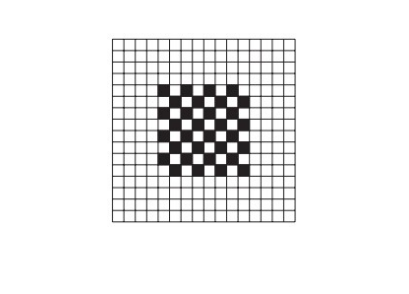

%Question 1. Finding the threshold value
img = imread('Pictures/chessboard.png');
imshow(img);

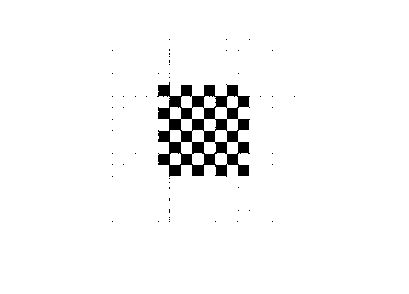


%converting to grayscale
I = im2gray(img);

%setting threshold
Thresh = 0.25;
I1 = imbinarize(I,Thresh * graythresh(I));
imshow(I1);


%Setting the threshold scalar to 0.25 can split the image
%into foreground and background

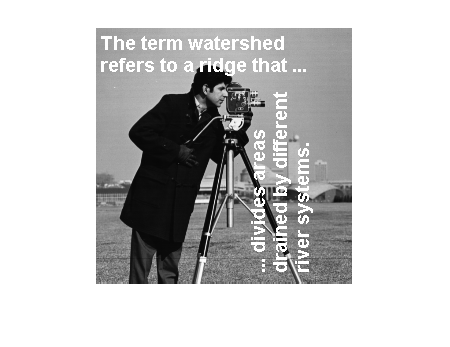


%Question 2. Superimposing text on cameraman
cam = imread("cameraman.tif");
text = imread("Downloads/text.tif");
m = uint8(double(cam)+255*double(text));
% m is the superimposed image
imshow(m);

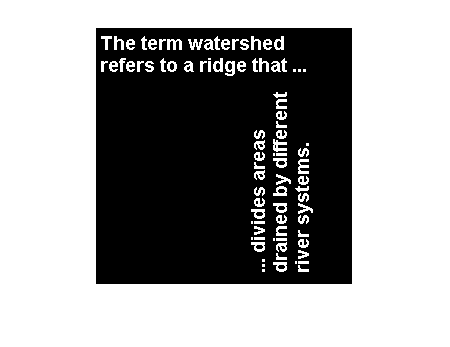


% I is the segmented part to isolate text
Threshold = 2.7;
I = imbinarize(m,Threshold * graythresh(m));
imshow(I);

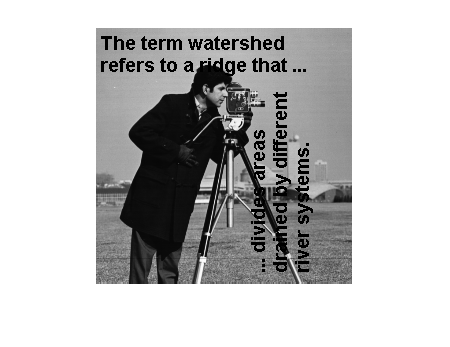

%Question 3. Using Different formula for m
cam = imread("cameraman.tif");
text = imread("Downloads/text.tif");
m = uint8(double(cam).*double(~text));
% m is superimposed image with black text
imshow(m);

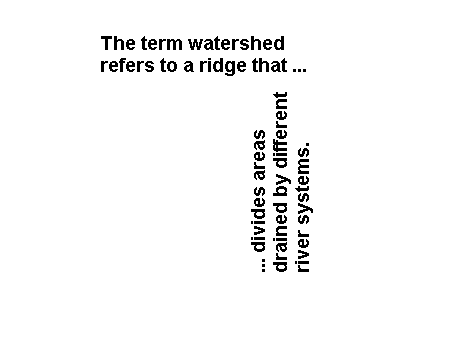


% I is the segmented part to isolate text
Threshold = 0;
I = imbinarize(m,Threshold * graythresh(m));
imshow(I);

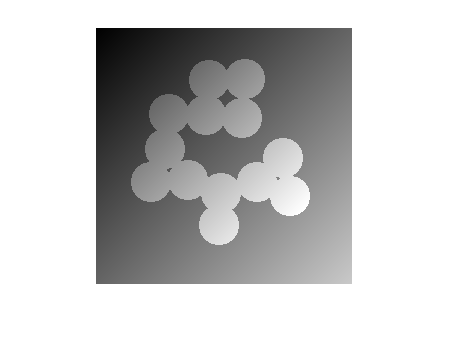

% Question 4. Circles
circle = imread("Downloads/circles.tif");
[x,y] = meshgrid(1:256,1:256);
t2 = double(circle).*((x+y)/2+64)+x+y;
t3 = uint8(255*mat2gray(t2));
imshow(t3);

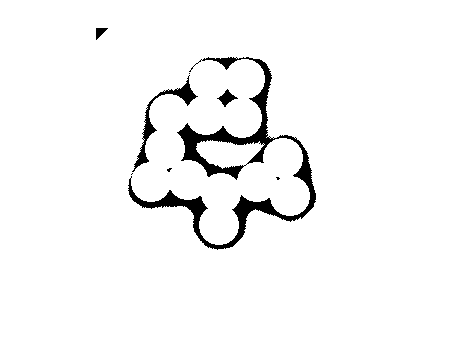

%Here t3 is the question img

%t4 is the answer
t4 = adapthisteq(t3);
Threshold = adaptthresh(t4,0.01);
t4 = imbinarize(t4,Threshold * graythresh(t4));
imshow(t4);

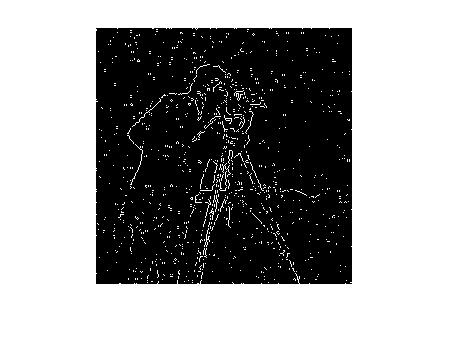

% Question 5. Adding noise and using edge finding methods
cam = imread('cameraman.tif');

%using in built salt and pepper function to add noise of density 0.1
c1 = imnoise(cam,'salt & pepper',0.1);

%using in built gaussian function to add noise of var 0.02 and 0 mean
c2 = imnoise(cam,'gaussian',0,0.02);

img1 = edge(c1,'Sobel');
imshow(img1);

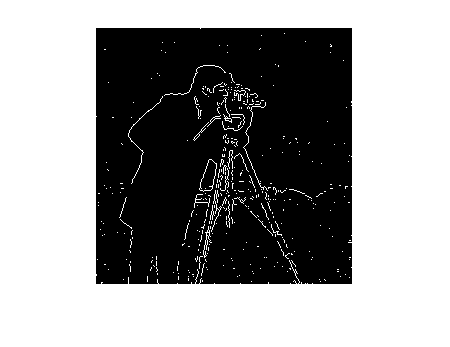

img2 = edge(c2,'Sobel');
imshow(img2);

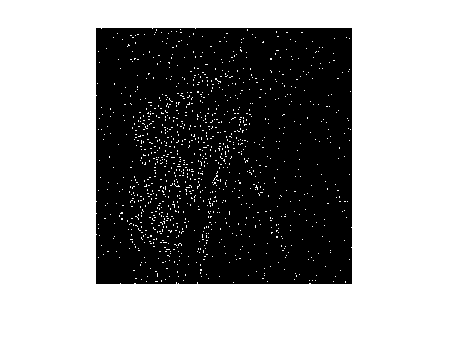


img1 = edge(c1,'Roberts');
imshow(img1);

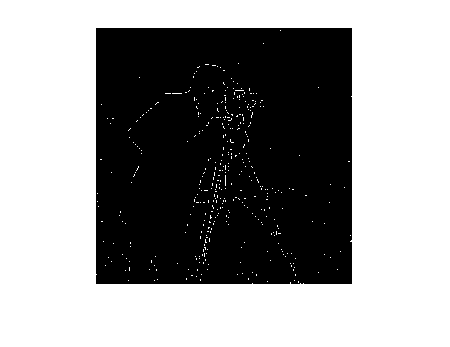

img2 = edge(c2,'Roberts');
imshow(img2);

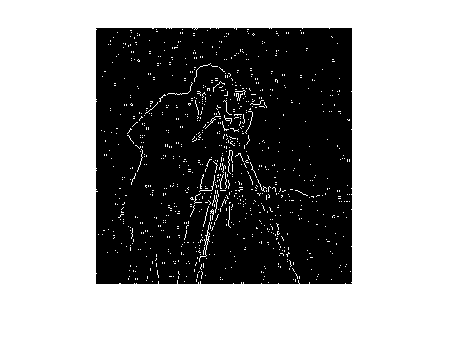


img1 = edge(c1,'Prewitt');
imshow(img1);

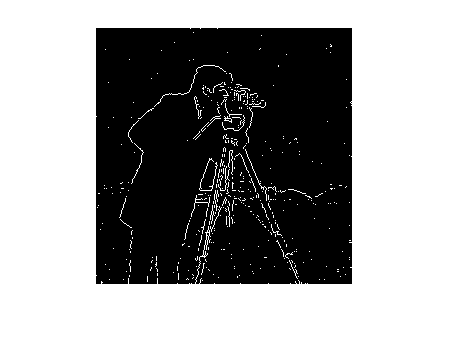

img2 = edge(c2,'Prewitt');
imshow(img2);


% we can see that Prewitt and Sobel give the better results
% while Roberts fails to give good edges in presence of noise.